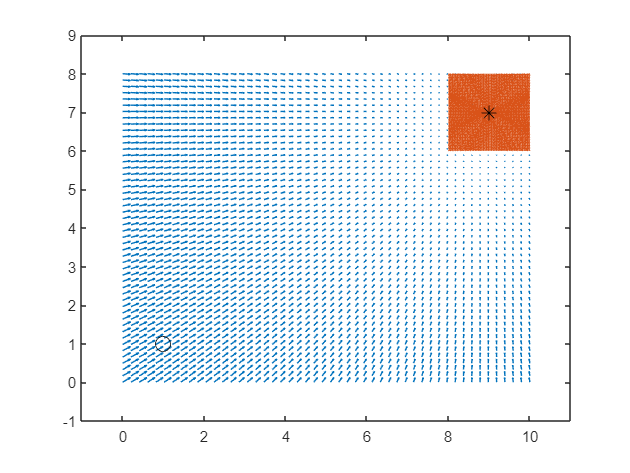

% Define the dimensions of the workspace
width = 10;
height = 8;

% Define the start and end points
start = [1, 1];
goal = [9, 7];

% Define the potential function
zeta = 10;

%Conical potential
U1 = @(x,y) zeta*sqrt((x - goal(1)).^2 + (y - goal(2)).^2);
%Quadratic potential
U2 = @(x,y) (zeta/2)*((x - goal(1)).^2 + (y - goal(2)).^2);

% Create a grid of points to evaluate the potential function
x = linspace(0, width, 50);
y = linspace(0, height, 50);
[X1,Y1] = meshgrid(x,y);
%-----------------------------------------------------------
x0 = goal(1);
y0 = goal(2);
r = 1;

% Create x and y values that span the range of the circle
x2 = linspace(x0-r, x0+r, 50);
y2 = linspace(y0-r, y0+r, 50);

% Create a meshgrid using the x and y values
[X_2, Y_2] = meshgrid(x2, y2);

% Create a logical matrix that represents the points inside the circle
logical_matrix = (X_2-x0).^2 + (Y_2-y0).^2 <= r^2;

% Use the logical matrix to filter the meshgrid and only keep the points inside the circle
X2 = X_2(logical_matrix);
Y2 = Y_2(logical_matrix);


%-----------------------------------------------------


% Evaluate the potential function at each point on the grid
Z_out = U2(X1,Y1);
Z_in = U1(X_2,Y_2);

% Calculate the gradient of the potential function
[dx_out, dy_out] = gradient(-Z_out);
[dx_in, dy_in] = gradient(-Z_in);

% Plot the potential vector field
quiver(X1,Y1,dx_out,dy_out);
hold on
quiver(X_2,Y_2,dx_in,dy_in,"filled","LineWidth",0.5);
% Plot the start and end points on the plot
hold on;
plot(start(1), start(2), 'ko', 'MarkerSize', 10);
plot(goal(1), goal(2), 'k*', 'MarkerSize', 10);
axis([-1 11 -1 9]);

%surf(x,y,Z_out,'FaceAlpha','0.5')
% hold on
% surf(x2,y2,Z_in,'FaceAlpha','0.5')